# **2. Satellite as rigid Body Motion Equations**

clear; clc
%%ANIMATION FLAG
animationsGraphs = true;

## **1. Background**

To conduct the satellite ADCS simulation, it is essential to construct a precise model that describes the rotational and translational dynamics of the spacecraft. In this section, we present the mathematical models derived from a rigid body.

### **1.1. Angular Momentum and Inertia Matrix**

According to [2], it is supposed that a rigid body is moving in an inertial frame therefore we need to define the transport theorem. 

#### 1.1.1 Transport theorem

The transport theorem is a usefull theorem that has a lot of aplications due to it relates an inertial frame and a rotational body frame [4]. To define the Transport theorem suppose we have a vector $A$ expressed in a reference frame $B$ (body Frame) and we want to find its derivative with respect to another reference frame $I$ (Inertial Frame). Then, the derivative of $A$ with respect to $I$ can be calculated as: 

${\left.\frac{d}{dt}A \right|}_I={\left.\frac{d}{dt}A \right|}_B + \omega_{IB} \times A,$   (1.1.1)

Eq. (1.1.1) explains that the change of vector $A$ in $I$ frame can be represented by the change of vector $A$ in the reference frame $B$  with an angular rate $\omega_{IB}$ (Angular rate from $B$ relative to $I$)  plus the vector product $\omega_{IB}\times A$.  

The following code present an example of the transport theorem to derive the relationship between an inertial Frame and a body frame that are depicted in Fig. 1.1.1.

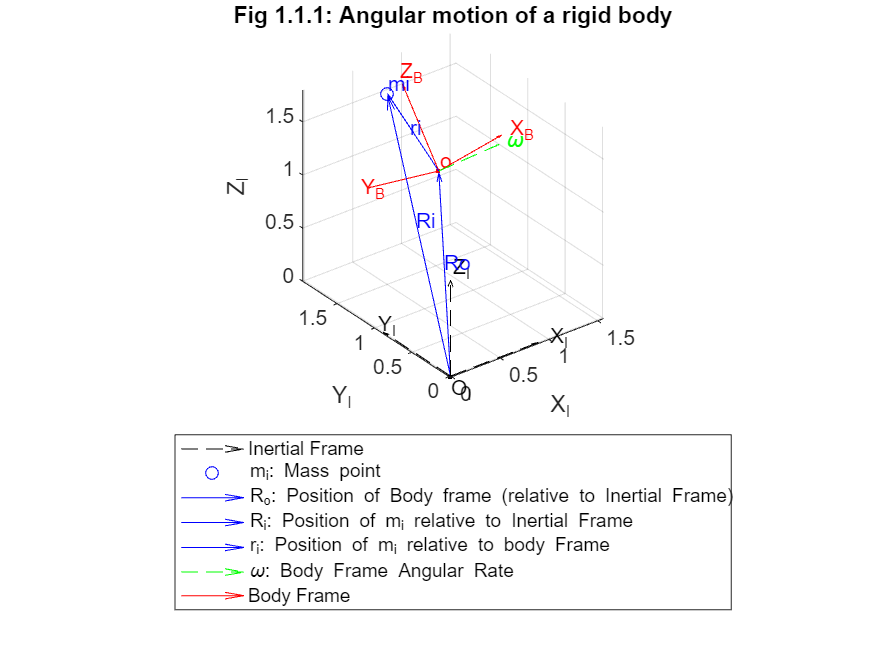

%%% Clear previous variables
clearvars -except animationsGraphs

figure()
%%% Define rotational Frame B
    %%% Define the unitary vector u
    yb = [-1,5,-3]/norm([-1,5,-3]);
    %%% Define a vector v perpendicular to u
    xb  = [yb(2), -yb(1), 0];
    %%% Define a vector v1 perpendicular to u and v
    zb = cross(xb,yb);
    %%% Angular rate from B relative to I
    omega = [0.3,-0.5,0.4];
    
%%% Define position vector of one point mi 
    Ro = [0.8, 1.2, 1.1]';  %Position of body Frame relative to I 
    Ri = [0.5, 1.5, 1.8]';  %Position of mi relative to I
    ri = Ri-Ro;             %Position of mi relative to B
 
%%% Plots
%%% Plot inertia frame 
    [h1,~] = plotVector(zeros(1,3), [1,0,0], 1, 'k--', 'X_I', 'e'); hold on;
             plotVector(zeros(1,3), [0,1,0], 1, 'k--', 'Y_I', 'e');
             plotVector(zeros(1,3), [0,0,1], 1, 'k--', 'Z_I', 'e');
             plotPoint (zeros(1,3),    'k.',  'O_I', -0.08);

%%% Plot Ro, Ri and ri vectors
    [h2,~] = plotPoint(Ri,'bo','mi',0.05);
    [h3,~] = plotVector(zeros(1,3),Ro,1,'b-','Ro','m');
    [h4,~] = plotVector(zeros(1,3),Ri,1,'b-','Ri','m');
    [h5,~] = plotVector(Ro,ri,1,'b-','ri','m');
    [h6,~] = plotVector(Ro,omega,1,'g--','\omega','e');

%%% Plot Rotational Frame
    [h7,~] = plotVector(Ro,yb,1,'r-','Y_B','e');
             plotVector(Ro,xb,1,'r-','X_B','e');
             plotVector(Ro,zb,1,'r-','Z_B','e');
             plotPoint(Ro,'r.','o',0.05);

%%% Plot settings
    title('Fig 1.1.1: Angular motion of a rigid body');
    xlabel('X_I'); ylabel('Y_I'); zlabel('Z_I');
    axis equal
    legend([h1, h2, h3, h4, h5, h6,h7], 'Inertial Frame','m_i: Mass point',...
           'R_o: Position of Body frame (relative to Inertial Frame)',...
           'R_i: Position of m_i relative to Inertial Frame',...
           'r_i: Position of m_i relative to body Frame', '\omega: Body Frame Angular Rate',...
           'Body Frame','Location','southoutside') ;

The following code shows an animation of Fig 1.1.1 for more understanding.

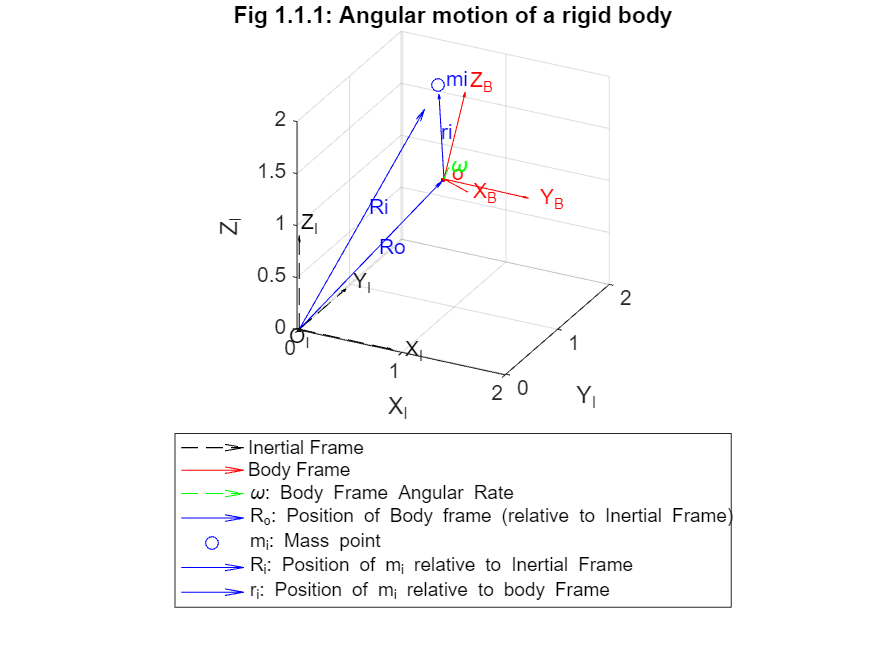

%%% Clear previous variables
clearvars -except animationsGraphs

%%% Define Parameters for rotation
    rad   = linspace(0,deg2rad(360),60);   %Rotation angle of mi poinr
    omega = [0.3,-0.5,0.4];                %Angular rate of mi point
    t     = rad/norm(omega);               %Time vector of the system
    
%%% Define rotational Frame B
    %%% Define the unitary vector yb
    yb = [-1,5,-3]/norm([-1,5,-3]);
    %%% Define a vector xb perpendicular to xb
    xb  = [yb(2), -yb(1), 0];
    %%% Define a vector zb perpendicular to xb and yb
    zb = cross(xb,yb);

%%% Define position vector of one point mi 
    Ro = [0.8, 1.2, 1.1]';    %Position of body Frame relative to I 
    Ri = [0.5, 1.5, 1.8]';    %Position of mi relative to I
    ri = Ri-Ro;               %Position of mi relative to B
    u = omega/norm(omega);    %Frame B rotation axis

%%% Calculate movement of mi point relative to I rotating the ri vector 
%%% and then add Ro to obtain the Ri vector trayectory over the time
    ri_v = zeros(3,length(t));                                  %Container to save rotated ri vectors     
    B_v = struct();
    for i = 1:length(t)
         %Calculate rotation Matrix arround u axis
        R = calculateRotationMatrix(u, rad(i));
        B_v.(['n_',num2str(i)]) = R*[xb;yb;zb]';
        ri_v(:,i)=R*ri;
    end
    
%%% Plot Figure
    figure()
    
    %%% Plot inertia frame I
    [h1,~] = plotVector(zeros(1,3), [1,0,0], 1, 'k--', 'X_I', 'e'); hold on
             plotVector(zeros(1,3), [0,1,0], 1, 'k--', 'Y_I', 'e');
             plotVector(zeros(1,3), [0,0,1], 1, 'k--', 'Z_I', 'e');
             plotPoint (zeros(1,3), 'k.', 'O_I', -0.08);
    
    %%% Plot Rotational Frame  
        B = B_v.(['n_',num2str(1)]); %% Get rotated frame
        [h2,  h3]  = plotVector(Ro, B(:,1),1, 'r-', 'Y_B', 'e');
        [h4,  h5]  = plotVector(Ro, B(:,2),1, 'r-', 'X_B', 'e');
        [h6,  h7]  = plotVector(Ro, B(:,3),1, 'r-', 'Z_B', 'e');
                     plotPoint (Ro, 'r.', 'o', 0.05);    
    %%% Plot angular rate from B relative to I
        [h8,~] = plotVector(Ro,omega, 1, 'g--', '\omega', 'e');
    
    %%% Plot Ro vector
        [h9,~] = plotVector(zeros(1,3),Ro,1,'b-','Ro','m');
   
    %%% Plot Ri and ri vectors
        Ri = ri_v(:,1)+Ro;
        [h10,h11] = plotPoint(Ri,'bo','mi',0.05);
        [h12,h13] = plotVector(zeros(1,3),Ri,1,'b-','Ri','m');
        [h14,h15] = plotVector(Ro,ri_v(:,1),1,'b-','ri','m');
    
    title('Fig 1.1.1: Angular motion of a rigid body');
    xlabel('X_I'); ylabel('Y_I'); zlabel('Z_I');
    axis equal
    legend([h1, h2, h8, h9, h10, h12, h14], 'Inertial Frame','Body Frame',...
           '\omega: Body Frame Angular Rate','R_o: Position of Body frame (relative to Inertial Frame)','m_i: Mass point',...
           'R_i: Position of m_i relative to Inertial Frame',...
           'r_i: Position of m_i relative to body Frame',...
           'Location','southoutside') ;
    xlim([0 2]);
    ylim([0 2]);
    zlim([0 2]);
    view([26.58 25.77]);
  
if (animationsGraphs)
    for i =  1:(length(t)-1) 
        %%Recover rotated ri_v and B frame
        B = B_v.(['n_',num2str(i)]);
        Ri = ri_v(:,i)+Ro;
        
        %%Refresh B frame
        set(h2, 'UData', B(1,1), 'VData', B(2,1), 'WData', B(3,1));      
        set(h3, 'Position', Ro+B(:,1));
        set(h4, 'UData', B(1,2), 'VData', B(2,2), 'WData', B(3,2));
        set(h5, 'Position', Ro+B(:,2));
        set(h6, 'UData', B(1,3), 'VData', B(2,3), 'WData', B(3,3));
        set(h7, 'Position', Ro+B(:,3));
        
        %%Refresh mi point
        set(h10, 'XData', Ri(1), 'YData', Ri(2), 'ZData', Ri(3));
        set(h11, 'Position', Ri+0.05);
        
        %%Refresh Ri vector
        set(h12, 'UData', Ri(1), 'VData', Ri(2), 'WData', Ri(3));
        set(h13, 'Position', Ri/2);
        %%Refresh ri vector
        set(h14, 'UData', ri_v(1,i), 'VData', ri_v(2,i), 'WData', ri_v(3,i));
        set(h15, 'Position', Ro+ri_v(:,i)/2);
              
        %%% Pause animation
        pause(0.01);
    end
end

In Fig. 1.1.1, we denote a body reference frame $B$ with the triad $(X_B, Y_B ,Z_B )$ centered in $o$ that is the center of mass of the system composed of $n$ points $P_1,P_2,...P_n$ denoted as $P_i$ asociated with mass $m_i$. $R_o$ is the position vector from the inertial frame (centered in $O_I$) to the center of mass of the system $O$ and $R_i$ is the position vector of the $P_i$ relative to inertial frame. From Fig. 1.1.1. we can notice that $R_i = R_o+r_i$ we can obtain $R_i$ derivative relative to inertial frame in the following sense:


$$\left . \dot R_i   \right| _ I = \left . \dot R_o   \right| _ I +\left . \dot r_i   \right| _ I $$


For $\left . \dot {r_i} \right |_I$ we can apply the transport theorem and therefore we got equation (1.1.2) [4].

$\left . \dot R_i   \right| _ I = \left . \dot R_o   \right| _ I +\left . \dot r_i   \right| _ B + \omega_{IB} \times r_i = v_0+v_i+\omega_{IB}\times r_i$   (1.1.2)

In the following code we implement a demonstration of equation (1.1.2) taking into consideration Fig. 1.1.1 and that $\left .\dot {R_o} \right| _I = 0$ and $\left. \dot{r_i} \right |_B=0$ due to the $B$ frame doesn't have any translational movement relative to $I$ and the $r_i$ vector doesn't change relative to $B$ frame.

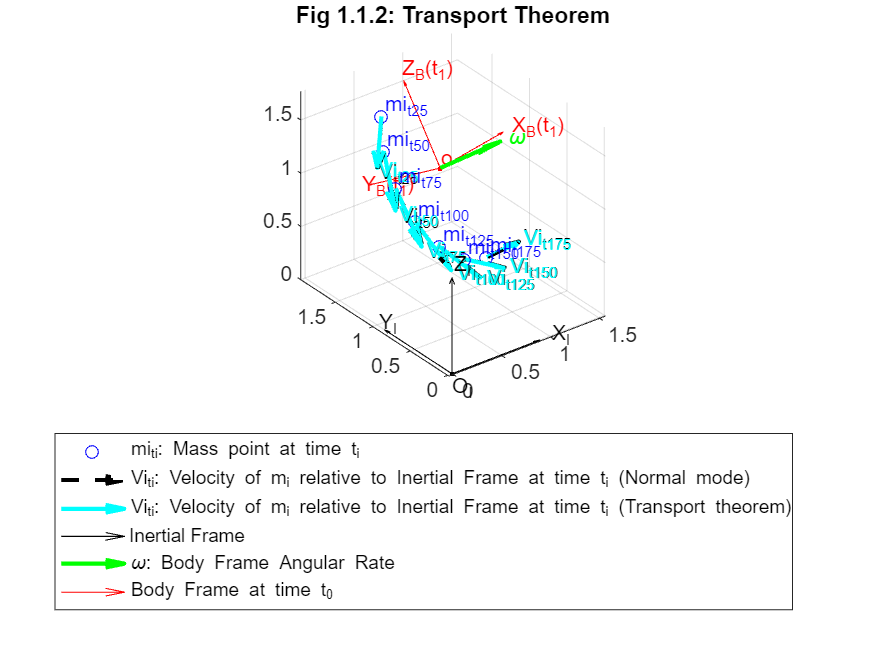

%%% Clear previous variables
clearvars -except animationsGraphs

figure()

%%% Define Parameters for rotation
    rad   = linspace(0,deg2rad(180),200);  %Rotation angle of mi poinr
    omega = [0.3,-0.5,0.4];                %Angular rate of mi point
    t     = rad/norm(omega);               %Time vector of the system

%%% Define rotational Frame B
    %%% Define the unitary vector u
    yb = [-1,5,-3]/norm([-1,5,-3]);
    %%% Define a vector v perpendicular a ur
    xb  = [yb(2), -yb(1), 0];
    %%% Define a vector v1 perpendicular to u and v
    zb = cross(xb,yb);

%%% Define position vector of one point mi 
    Ro = [0.8, 1.2, 1.1]';    %Position of body Frame relative to I 
    Ri = [0.5, 1.5, 1.8]';    %Position of mi relative to I
    ri = Ri-Ro;               %Position of mi relative to B
    u = omega/norm(omega);    %Frame B rotation axis

%%% Calculate movement of mi point relative to I rotating the ri vector 
%%% and then add Ro to obtain the Ri vector trayectory over the time
    ri_v = zeros(3,length(t));                                  %Container to save rotated ri vectors                  
    for i = 1:length(t)
        R = calculateRotationMatrix(u, rad(i)); %Calculate rotation Matrix arround u axis
        ri_v(:,i)=R*ri;
    end

%%% Calculate Ri rate relative to I by conventional form
    Ri_v = ri_v+Ro;
    Ri_dot_I = diff((Ri_v)')'./diff(t);

%%% Calculate Ri rate relative to I by transport theorem eq 1.1.2
    Ro_dot_B = 0;       %Zero due to B does not have translational diplacement relative to I
    ri_dot_B = 0;       %Zero due to ri does not have translationa displacement relative to B
    Ri_dot_I1 = Ro_dot_B + ri_dot_B + cross(omega.*ones(200,3),ri_v');     %Transport theorem
    
%%% Plot settings
    figure()
    capture_time = 25;  %Plot velocity each 20 seconds

%%% Plot Ri_dot relative to I
    for i = 1:length(Ri_v)-1
        if mod(i,capture_time) == 0
            %%% Plot mi points over time
            [h1,~] = plotPoint(ri_v(:,i)+Ro,'bo',['mi_{t',num2str(i),'}'],0.05);
            hold on
            %%% Plot Ri_dot relative to I calculated by conventional mode    
            [h2,~] = plotVector(Ri_v(:,i+1),Ri_dot_I(:,i),1,'K--',['Vi_{t',num2str(i),'}'],'e');
            set(h2,'Linewidth',2,'MaxHeadSize',2);
            %%% Plot Ri_dot relative to I calculated by transport theorem
            [ha,~] = plotVector(Ri_v(:,i),  Ri_dot_I1(i,:) ,1,'c-',['Vi_{t',num2str(i),'}'],'e');
            set(ha,'Linewidth',2,'MaxHeadSize',2);
        end
    end
    
%%% Plot inertia frame I
    [h4,~] = plotVector(zeros(1,3), [1,0,0], 1, 'k-', 'X_I', 'e');
             plotVector(zeros(1,3), [0,1,0], 1, 'k-', 'Y_I', 'e');
             plotVector(zeros(1,3), [0,0,1], 1, 'k-', 'Z_I', 'e');
             plotPoint (zeros(1,3), 'k.', 'O_I', -0.08);
 
%%% Plot angular rate from B relative to I
    [h5,~] = plotVector(Ro,omega, 1, 'g-', '\omega', 'e');
    set(h5,'Linewidth',2,'MaxHeadSize',2);
    
%%% Plot Rotational Frame
    [h6,~] = plotVector(Ro, yb,1, 'r-', 'Y_B(t_1)', 'e');
             plotVector(Ro, xb,1, 'r-', 'X_B(t_1)', 'e');
             plotVector(Ro, zb,1, 'r-', 'Z_B(t_1)', 'e');
             plotPoint (Ro, 'r.', 'o', 0.05);
             
%%% Plot settings
title('Fig 1.1.2: Transport Theorem')
axis equal
    legend([h1, h2, ha, h4, h5, h6], 'mi_{ti}: Mass point at time t_i',...
           'Vi_{ti}: Velocity of m_i relative to Inertial Frame at time t_i (Normal mode)',...
           'Vi_{ti}: Velocity of m_i relative to Inertial Frame at time t_i (Transport theorem)',...
           'Inertial Frame', '\omega: Body Frame Angular Rate', 'Body Frame at time t_0',...
           'Location','southoutside');

As depicted in Fig. 1.1.2, we observe an equivalence between the transport theorem and the derivative of the inertial frame, noting that they are identical. According to references [2] and [5], we can define the moment of momentum for any particle within the body. Therefore:

$h_i = r_i\times m_i \dot {R_i} = r_i \times m_i (\dot {R_o} + \dot{r_i}+\omega \times r_i)$   (1.1.3.)

Due to we are talking about a rigid body we know that $\dot {r_i} = 0$.


$$h_i = r_i \times m_i (\dot {R_o} + \omega \times r_i) = -v_0 \times m_ir_i + r_i\times m_i (\omega \times r_i)$$
 

Due to we consider that there are several particles in the system, to find the angulat momentum of the entire body, we shall sum the momentum components of all the mass particles.$h = \sum_{m_i} - v_0 \times m_i r_i + \sum_{m_i} r_i \times (\omega \times r_i)m_i = -v_0 \times \sum_{m_i} m_i r_i + \sum_{m_i}r_i\times(\omega\times r_i) m_i$

Considering that the angular motion is about the center of mass we got that$\sum_{m_i} m_ir_i = 0$. Then, we got:


$$h=\sum_{m_i} r_i\times(\omega\times r_i)m_i$$


After several arrays in mathematical form, according to [2] and [5] we obtain equation.

$h=\left\lbrack \begin{array}{ccc}
I_{\textrm{xx}}  & I_{\textrm{xy}}  & I_{\textrm{xz}} \\
I_{\textrm{xy}}  & I_{\textrm{yy}}  & I_{\textrm{yz}} \\
I_{\textrm{xz}}  & I_{\textrm{yz}}  & I_{\textrm{zz}} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\omega_x \\
\omega_y \\
\omega_z 
\end{array}\right\rbrack =\left\lbrack I\right\rbrack \omega$ (1.1.4)

It is important to denote that $[I]$ is the inertia tensor in reference of the body Frame and the $\omega$ vector is the angular rate from body fram $B$ relative to $I$. According to [2] there are several ways to solve the eq 1.1.4 analiticaly, but these methods requires the simplification of the system considering some symetries.

**1.2.  Rotational Dynamics**

#### **1.2.1 Euler's Moment Equations**

According to [2] the angular momentum in the inertial frame can be calculated relative to the inertial frame appliyng the translational theorem. This formula is derived with the aim to examinate the rotational motion of a body caused by th applied moment.

$M = \dot{h_I} = \dot{h_B} + \omega \times h_B$  (1.2.1)

Eq. 1.2.1 is known as the Euler's moment equation and from there we can obtain the equations of motion for spacecraft Attitude.

$T = \dot{h_I} = \dot{h} + \omega \times h$          (1.2.2.)

Where $T$ is understood as external torques which can be break down as control moments ($T_c$) and environmental disturbances ($T_d$) in the way that $T = T_c + T_d$ and the momentum of the entire system is divided between the momentum of the rigid body $h_B$ and the momentum of the moment exchange devices $h_W$. In the way that $h=h_B+h_W$. With these definitions, eq (1.2.2.) becomes:

$T_c + T_d = \dot{h_B} + \dot{h_W} + \omega \times (h_B + h_W)$   (1.2.3.)

 Considering the case that only a rigid body is considered  then $h_W=0$ and the equation (1.2.3) becomes:


$$T_c+T_d = \dot{h_B} +\omega \times (h_B) = T_c+T_d = [I] \dot{\omega} + \omega \times ([I] \omega)$$


$\dot{\omega} = [I]^{-1} [T_c+T_d - \omega \times ([I] \omega)]$    (1.2.4)

Eq. (1.2.4) it is called the dynamic equation. The following code presents an implementation of this equation.

#### 1.2.2. Rotational Dynamics simulation

In the following code we implement a simulation to emulate the rotational dynamics of a rigid body under externarl torques.

%%% Clear previous variables
clearvars -except animationsGraphs
clear persistent
clear global

%%% Global variables
global varNames curValues varValues
varNames = {'T'};
curValues = struct(); varValues = struct();

%%% Satellite Inertia Properties
Is = [0.103682,-0.001094,0.015519;...
    -0.001094,0.104158,-2.57e-6;...
     0.015519,2.57e-6,0.088588];

%%% External disturbances
disturbance = @(t) stepper(t, [0,0,5]',1, 1.5);

%%% Initial conditions
omega_0 = [0,0,0]';
%%% Simulation settings
tfinal = 10;
tspan = [0 tfinal];

% Función de eventos para almacenar u(t) en cada paso
odeopts = odeset('Events', @(t, x) store_var(t, x));
[tout,omega] = ode45(@(t,x) mySatellite(t,x,Is,disturbance),tspan,omega_0,odeopts);

The following variables are recording.
    {'T'}



%%% Recover the torque
dist = zeros(3,length(tout));
for i = 1:length(tout)
    dist(:,i) = disturbance(tout(i));
end

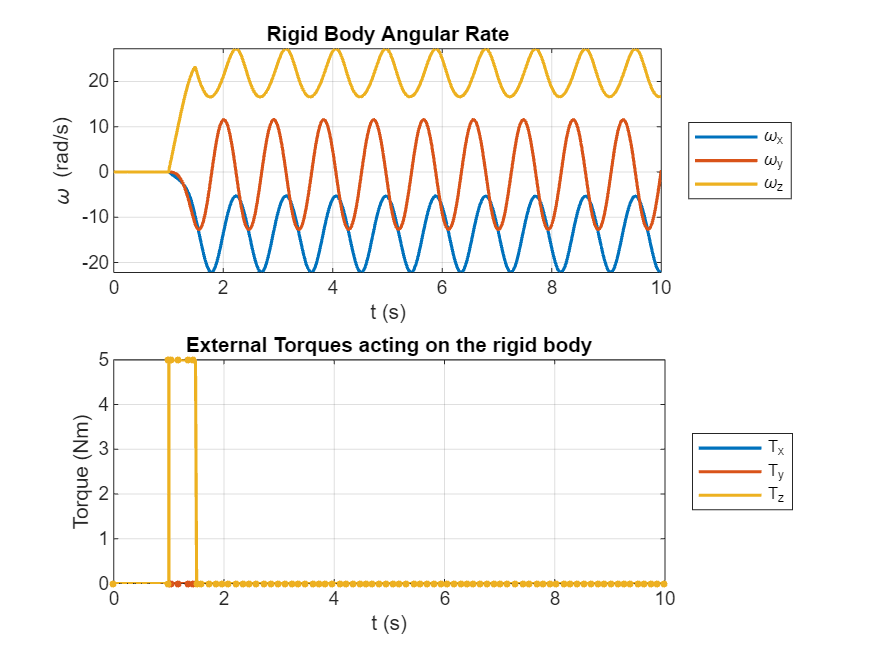

figure()
d1 = subplot(2,1,1);
plot(tout, omega,'LineWidth',1.5);

% Add legends and plot settings
legend('\omega_x','\omega_y','\omega_z','Location','eastoutside');
title('Rigid Body Angular Rate');
ylabel('\omega (rad/s)')
xlabel('t (s)')
grid on;

d2 = subplot(2,1,2);
plot(tout, dist,'-','LineWidth',1.5);hold on
p=plot(varValues.time,varValues.T,'.','MarkerSize',10); 
set(p(1),'Color',[0.00,0.45,0.74]);set(p(2),'Color',[0.85,0.33,0.10]);
set(p(3),'Color',[0.93,0.69,0.13]);
legend('T_x','T_y','T_z','Location','eastoutside');
title('External Torques acting on the rigid body');
ylabel('Torque (Nm)')
xlabel('t (s)')
grid on
linkaxes([d1,d2],'x');

For best understanding we implemt a 3D simulation for the obtaineda angular rate.

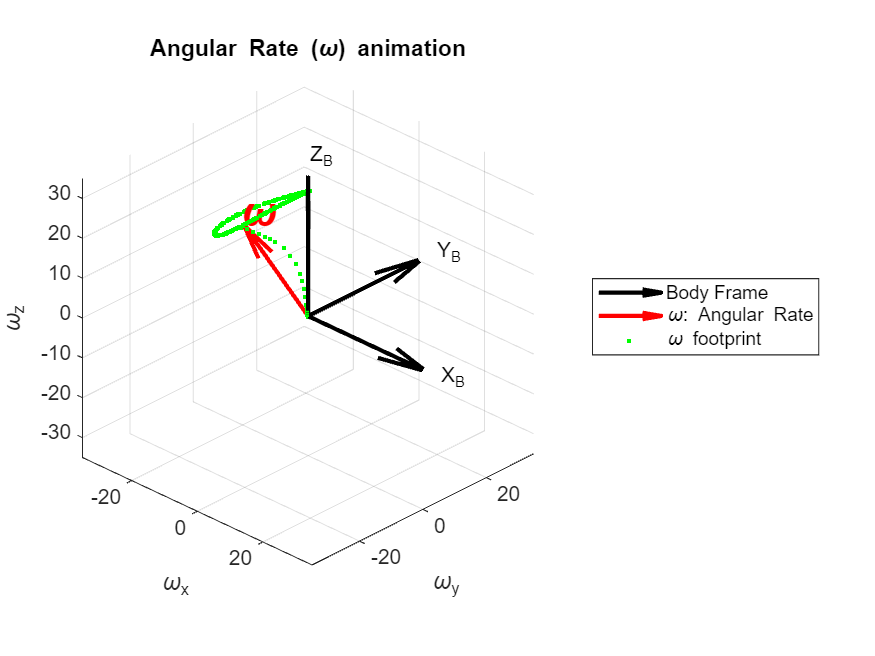

%% Figure to depict the 

figure()
scale = 40;

%%% Plot inertia frame I
[h4,~] = plotVector(zeros(1,3), [1,0,0], scale, 'k-', 'X_B', 'e'); hold on
set(h4,'LineWidth',2,'MaxHeadSize',2);
[h5,~] = plotVector(zeros(1,3), [0,1,0], scale, 'k-', 'Y_B', 'e');
set(h5,'LineWidth',2,'MaxHeadSize',2);
[h6,~] = plotVector(zeros(1,3), [0,0,1], scale, 'k-', 'Z_B', 'e');
set(h6,'LineWidth',2,'MaxHeadSize',2);
         
title('Angular Rate (\omega) animation');
xlabel('\omega_x'); ylabel('\omega_y'); zlabel('\omega_z');
grid on; axis equal;

if (animationsGraphs)
    [h1,h2] = plotVector(zeros(1,3),omega(1,:),1,'r-','\omega','e'); %#ok
    set(h1,'LineWidth',2,'MaxHeadSize',2);set(h2,'FontSize',20,'FontWeight','bold');
    
    for i =  1:length(omega)
        h3 = plot3(omega(i,1),omega(i,2),omega(i,3),'g.');
        set(h1, 'UData', omega(i,1), 'VData', omega(i,2), 'WData', omega(i,3));      
        set(h2, 'Position', omega(i,:));
        xlim([-35 35]); ylim([-35 35]); zlim([-35 35]);view([44 29]);
        %%% Pause animation
        pause(0.001);
    end
    
else
    [h1,h2] = plotVector(zeros(1,3),omega(end,:),1,'r-','\omega','e');
    set(h1,'LineWidth',2,'MaxHeadSize',2); set(h2,'FontSize',20,'FontWeight','bold');
    h3 = plot3(omega(:,1),omega(:,2),omega(:,3),'g.');
    xlim([-35 35]); ylim([-35 35]); zlim([-35 35]);view([44 29]);
end
    legend([h4, h1, h3],'Body Frame','\omega: Angular Rate','\omega footprint','Location','eastoutside');

As can be seen, equation (1.2.4) only correlates the external forces and the angular rates corresponding to the rigid body with an inertia tensor called $Is$.

### 1.3. Attitude Parameters 

#### 1.3.1. Quaternions

The kinematic equation describes the Satellite attitude from the orbit frame without takin into consideration any forces. Quaternions are the most common way to represent microsatellite attitude due to its global property (no singularities) and low computational cost (O). 

Therefore, in the following part we will focus in the use of quaternions as attitude parameters. The kinematic equation with quaternions is described by Equation (1.3.1).

$\dot q = \frac{1}{2}\Xi(q)$ (1.3.1)

Where $\Xi(q)$ is described by equation (1.3.2).

$\Xi \left(q\right)=\left\lbrack \begin{array}{ccc}
q_4  & -q_3  & q_2 \\
q_3  & q_4  & -q_1 \\
-q_2  & q_1  & q_4 \\
-q_1  & -q_2  & -q_3 
\end{array}\right\rbrack$ (1.3.2)

In Equation (1.3.1) and (1.3.2), $q$ is a quaternion that describes the rotation from the inertial frame to the body frame and has the following form:

$q = [q_1, q_2, q_3, q_4]^T$  (1.3.3)

A quaternion has a scalar part denoted by $q_4$ and a vector part denoted by $q_{13} = [q_1, q_2, q_3]^T$.

The rotation of a point $x = [x_1, x_2, x_3]^T$ under a rotation described by a quaternion $q$ equivalent to a rotation matrix $A$ can be described in the following form:

$q\otimes {x\otimes \;q}^* =\;\left\lbrack \begin{array}{c}
A\;x\\
0
\end{array}\right\rbrack$ (1.3.4)

Where $\otimes$ is denoted as the quaternion multiplication defined by [5]. That multiplication has the form:


$$q\otimes \;x=\left\lbrack q\otimes \right\rbrack x=\left\lbrack \begin{array}{cc}
\psi \left(q\right) & q
\end{array}\right\rbrack \;x$$


Where $\psi (q)$ has the form:


$$\psi \left(q\right)=\left\lbrack \begin{array}{c}
q_4 I_3 -\left\lbrack q_{1:3} \times \right\rbrack \\
-q_{1:3}^T 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
q_4  & -q_3  & -q_2 \\
-q_3  & q_4  & q_1 \\
q_2  & -q_1  & q_4 \\
-q_1  & -q_2  & -q_3 
\end{array}\right\rbrack$$


Additionally, $q^*$ is denoted as the conjugate of a quaternion and is defined as:


$$q^* =\left\lbrack \begin{array}{c}
-q_{1:3} \\
q_4 
\end{array}\right\rbrack$$


Simulation of the satellite under a step input.

%%% Clear previous variables
clearvars -except animationsGraphs
clear persistent
clear global

%%% Global variables
global varNames curValues varValues %#ok
varNames = {'T'};
curValues = struct(); varValues = struct();

%%% Satellite Inertia Properties
 Is = [0.103682,-0.001094,0.015519;...
     -0.001094,0.104158,-2.57e-6;...
      0.015519,2.57e-6,0.088588];

%%% External disturbances
disturbance = @(t) stepper(t, [0,0,5]',1, 1.5);
%%% Initial conditions
init.omega_0 = [0,0,0]';
init.rpy = deg2rad([0,0,0]);
init.q0123=EulerAngles2Quaternions(init.rpy);
init.x0=[init.q0123;init.omega_0];

%%% Simulation settings
tfinal = 10;
tspan = [0 tfinal];
% Función de eventos para almacenar u(t) en cada paso
odeopts = odeset('Events', @(t, x) store_var(t, x));
[tout,x] = ode45(@(t,x) satelliteQuat(t,x,Is,disturbance),tspan,init.x0,odeopts);

The following variables are recording.
    {'T'}




%%% Recover the torque
dist = zeros(3,length(tout));
for i = 1:length(tout)
    dist(:,i) = disturbance(tout(i));
end

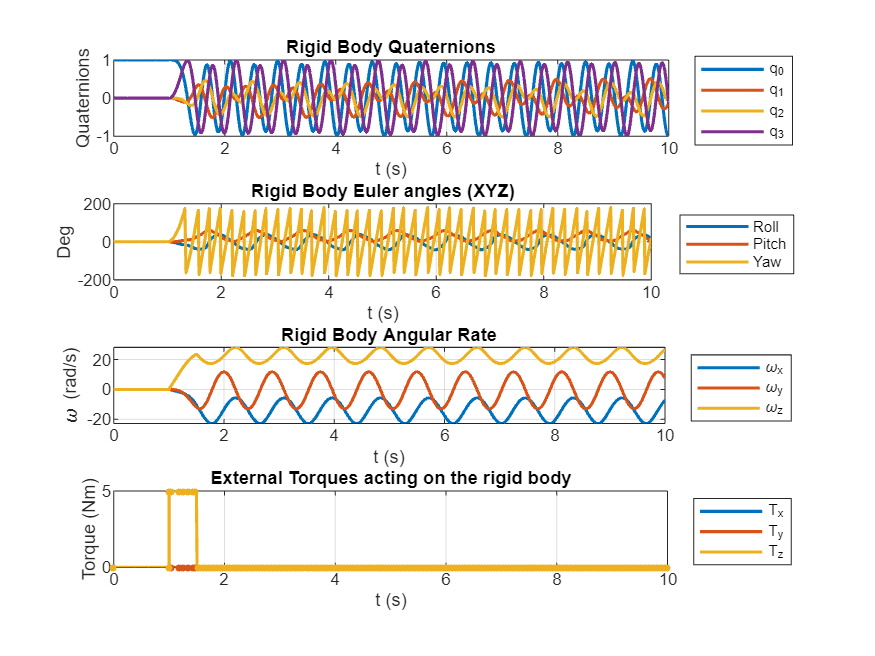

%%% Recover output
qout = x(:,1:4);
rpyout = rad2deg(Quaternions2EulerAngles(qout));
wout = x(:,5:7);

figure()
d1 = subplot(4,1,1);
plot(tout, qout,'LineWidth',1.5);

% Add legends and plot settings
legend('q_0','q_1','q_2','q_3','Location','eastoutside');
title('Rigid Body Quaternions');
ylabel('Quaternions')
xlabel('t (s)')
grid on;

d2 = subplot(4,1,2);
plot(tout, rpyout,'LineWidth',1.5); 
% Add legends and plot settings
legend('Roll','Pitch','Yaw','Location','eastoutside');
title('Rigid Body Euler angles (XYZ)');
ylabel('Deg')
xlabel('t (s)')
grid on;

d3 = subplot(4,1,3);
plot(tout, wout,'LineWidth',1.5);
% Add legends and plot settings
legend('\omega_x','\omega_y','\omega_z','Location','eastoutside');
title('Rigid Body Angular Rate');
ylabel('\omega (rad/s)')
xlabel('t (s)')
grid on;

d4 = subplot(4,1,4);
plot(tout, dist,'LineWidth',1.5); hold on;
p = plot(varValues.time,varValues.T,'.','MarkerSize',10);
set(p(1),'Color',[0.00,0.45,0.74]);set(p(2),'Color',[0.85,0.33,0.10]);
set(p(3),'Color',[0.93,0.69,0.13]);
legend('T_x','T_y','T_z','Location','eastoutside');
title('External Torques acting on the rigid body');
ylabel('Torque (Nm)')
xlabel('t (s)')
grid on
linkaxes([d1,d2,d3,d4], 'x');

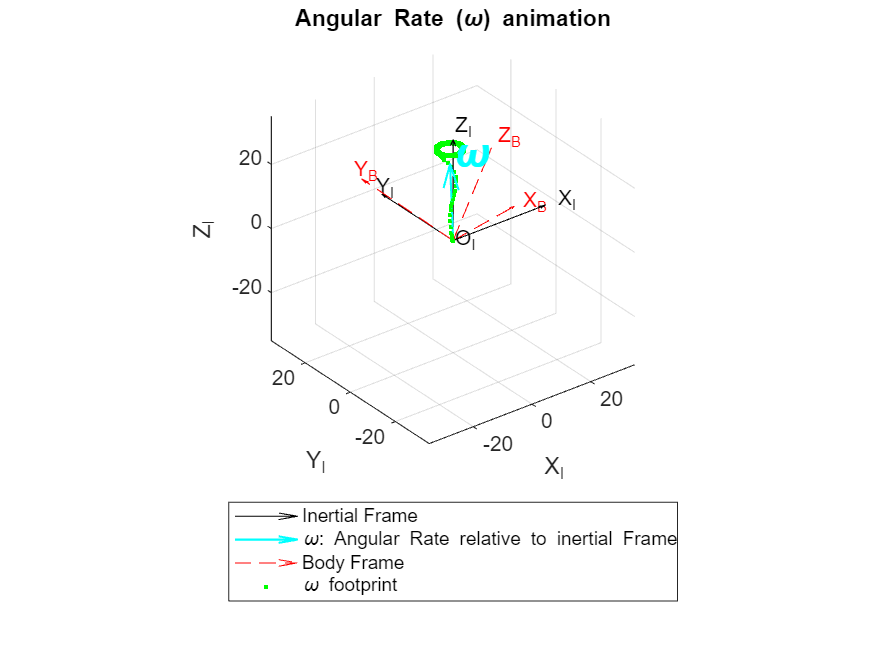

figure()
scaleFrames = 35;
scaleAngRate = 1;
%%% Plot inertia frame I
[h1,~] = plotVector(zeros(1,3), [1,0,0], scaleFrames, 'k-', 'X_I', 'e'); hold on
plotVector(zeros(1,3), [0,1,0], scaleFrames, 'k-', 'Y_I', 'e');
plotVector(zeros(1,3), [0,0,1], scaleFrames, 'k-', 'Z_I', 'e');
plotPoint (zeros(1,3), 'k.', 'O_I', -0.08);
title('Angular Rate (\omega) animation');
xlabel('X_I'); ylabel('Y_I'); zlabel('Z_I');
xlim([-35 35]); ylim([-35 35]); zlim([-35 35]);

%Preallocate variables
wout_i_V = zeros(length(x),3);
ri_v = struct();

for i = 1:length(x) 
     %Calculate rotated body Frame
     axisx = quatRotation(qout(i,:)',[1,0,0]');
     axisy = quatRotation(qout(i,:)',[0,1,0]');
     axisz = quatRotation(qout(i,:)',[0,0,1]');
     ri_v.(['n_',num2str(i)]) = [axisx',axisy',axisz'];
    
    %Calculate rotated angular rate
    wout_i_V(i,:) = quatRotation(qout(i,:)',wout(i,:)');
end

if (animationsGraphs)
    %%% Plot angular rate
    [h2, h3]  = plotVector(zeros(1,3), quatRotation(qout(1,:)',wout(1,:)') ,scaleAngRate,'c-','\omega','e'); 
    set(h2,'LineWidth',1,'MaxHeadSize',1); set(h3,'FontSize',20,'FontWeight','bold');
    %%% Plot Body Frame
    [h4,  h5]  = plotVector(zeros(1,3), quatRotation(qout(1,:)',[1,0,0]'),scaleFrames, 'r--', 'X_B', 'e');
    [h6,  h7]  = plotVector(zeros(1,3), quatRotation(qout(1,:)',[0,1,0]'),scaleFrames, 'r--', 'Y_B', 'e');
    [h8,  h9]  = plotVector(zeros(1,3), quatRotation(qout(1,:)',[0,0,1]'),scaleFrames, 'r--', 'Z_B', 'e');
            
    for i =  1:length(x)
        B = ri_v.(['n_',num2str(i)])*scaleFrames;
        ww = wout_i_V(i,:);
        
        h10 = plot3(ww(1)*scaleAngRate,ww(2)*scaleAngRate,ww(3)*scaleAngRate,'g.');
    
        set(h2, 'UData', ww(1)*scaleAngRate, 'VData', ww(2)*scaleAngRate, 'WData', ww(3)*scaleAngRate);
        set(h3, 'Position', ww*scaleAngRate);
    
        set(h4, 'UData', B(1,1), 'VData', B(2,1), 'WData', B(3,1));      
        set(h5, 'Position', B(:,1));
    
        set(h6, 'UData', B(1,2), 'VData', B(2,2), 'WData', B(3,2));      
        set(h7, 'Position', B(:,2));
    
        set(h8, 'UData', B(1,3), 'VData', B(2,3), 'WData', B(3,3));      
        set(h9, 'Position', B(:,3));
        
        xlim([-35 35]); ylim([-35 35]); zlim([-35 35]);
        
        %%% Pause animation
        pause(0.001);
    end
else
    [h2, h3]  = plotVector(zeros(1,3), quatRotation(qout(end,:)',wout(end,:)') ,scaleAngRate,'c-','\omega','e');
    set(h2,'LineWidth',1,'MaxHeadSize',1); set(h3,'FontSize',20,'FontWeight','bold');
    %%% Plot Body Frame
    [h4,  h5]  = plotVector(zeros(1,3), quatRotation(qout(end,:)',[1,0,0]'),scaleFrames, 'r--', 'X_B', 'e');
    [h6,  h7]  = plotVector(zeros(1,3), quatRotation(qout(end,:)',[0,1,0]'),scaleFrames, 'r--', 'Y_B', 'e');
    [h8,  h9]  = plotVector(zeros(1,3), quatRotation(qout(end,:)',[0,0,1]'),scaleFrames, 'r--', 'Z_B', 'e');
    
    h10 = plot3(wout_i_V(:,1)*scaleAngRate,wout_i_V(:,2)*scaleAngRate,wout_i_V(:,3)*scaleAngRate,'g.');
    xlim([-35 35]); ylim([-35 35]); zlim([-35 35]);
end
legend([h1, h2, h8, h10],'Inertial Frame','\omega: Angular Rate relative to inertial Frame','Body Frame','\omega footprint','Location','southoutside');

### 1.4.Translational Dynamics

#### 1.4.1 The Laws of Kepler and Newton

The Kepler Laws are empirical Laws for planetary motion based on Brahes's planetary observations.  Newton provided three laws of mechanics and one for gravitational attraction wich are formulated as follows:

- Every particle reamins in state of rest, or of uniform motion in a stright line with constant velocity, unless acted upon by an external force.

- The rate of change of linear momentum of a body is equal to the force F applied on the body, where $p = mv$ is the linear momentum.


$$F = \frac{dp}{dt} = \frac{d(mv)}{dt}$$


              In this equation, $m$ is the mass of the body and v is the velocity vector. In case of a constant mass, this law takes the simplified form: 

$F = m \frac{dv}{dt} = m a$  (1.4.1)

- For any force denoted as $F_{12}$ exerted by particle 1 on a particle 2, there must likewise exist a force $F_{21}$ exerted by particle 2 on particle 1 equal in magnitude and opposite in direction. $F_{12} = - F_{21}$

- Any two particles attract each other with a force given by the expresion.

$F=\frac{Gm_1m_2r}{r^3}$   (1.4.2)

            Where r is a vector of magnitude r along the line connecting the two particles with masses $m_1$ and $m_2$ and $G = 6.668E-11 m^3 / kg - s^2$ is the universal constant of gravitation. This is the famous inverse square law of forcce; the magnitude of the force is 

$F = \frac{G m_1 m_2}{r^2}$.

#### 1.4.2. The two body Problem

The two body problem is an idealized situation where only two bodies exist that are in relative motion in a force field described by equation (1.4.2). 

In case of spacecraft it is assumed that additional bodies are situated far away thus a third body is not considered. 

We can consider a system (Fig.1.4.2) with two points denoted as $p_1$and $p_2$ with mass $m_1$ ans $m_2$ exerts and attraction forces $F_2 = m_2 \ddot{r_2}$ and $F_1 = m_1 \ddot{r_1}$ respectivecly over each other.

The forces can be described as:

$F_1 = m_1 \ddot{r_1} = Gm_1m_2\frac{r_2-r_1}{|r_2-r_1|^3$  (1.4.3)

$F_2 = m_2\ddot{r_2} = G m_1 m_2 \frac{r_1-r_2}{|r_1-r_2|^3} = -F_1$ (1.4.4.)

From Eq (1.4.3) and (1.4.4) we find.


$$\ddot{r_2} - \ddot{r_1} = -G(m_1 + m_2) \frac{r_2 - r_1}{r^3}$$


and since $r = r_2 -r_1$


$$\ddot {r} + G(m_1 + m_2)\frac{r}{r^3} = 0$$
     

The center of mass of the system is calculated by $\sum m_j r_i = 0$; it follows that $r_am_1 - r_b m_2 = 0$. $r_c$ is the radius vector from the origin of the reference frame to the cm of the two body system, and $r_a = r_c - r_1$ and $r_b = r_2 - r_c$ or equivalently $m_1(r_c - r_1) - m_2 (r_2 - r_c) = 0$. Hence

$r_c(m_1 + m_2 ) = m_1 r_1 +m_2 r_2$      (1.4.5.)

After two diferentiations and taking into consideration (1.4.3) and (1.4.4)  we find that

$\ddot{r_c} = 0$  and $\dot{r_c} = const$

That means that although the cm is not accelerated, the system can be in rectilinear motion with constant velocity.

Aditionally, is we use the definition of the center of mass of the two-body system, we find that $r_b = r_a (m_1 / m_2)$ and $r=r_a(1+m_1/m_2)$. After differentiation, we obtain:

$\ddot{r_a} = \ddot{r}\frac{m_2}{m_1+m_2}$ ; and $\ddot{r_b} = \ddot{r}\frac{m_1}{m_1+m_2}$

If $m_1 \gg m_2$, then $\ddot{r_a} = \ddot{r}\frac{m_2}{m_1}\rightarrow 0$ and $\ddot{r_b} = \ddot{r}$. This leads the conclussion that if the $m_2$ is smaller than $m_1$, $m_2$ doesn't has influence on the motion of the much larger body $m_1$, which can be seen as an inertial body. 

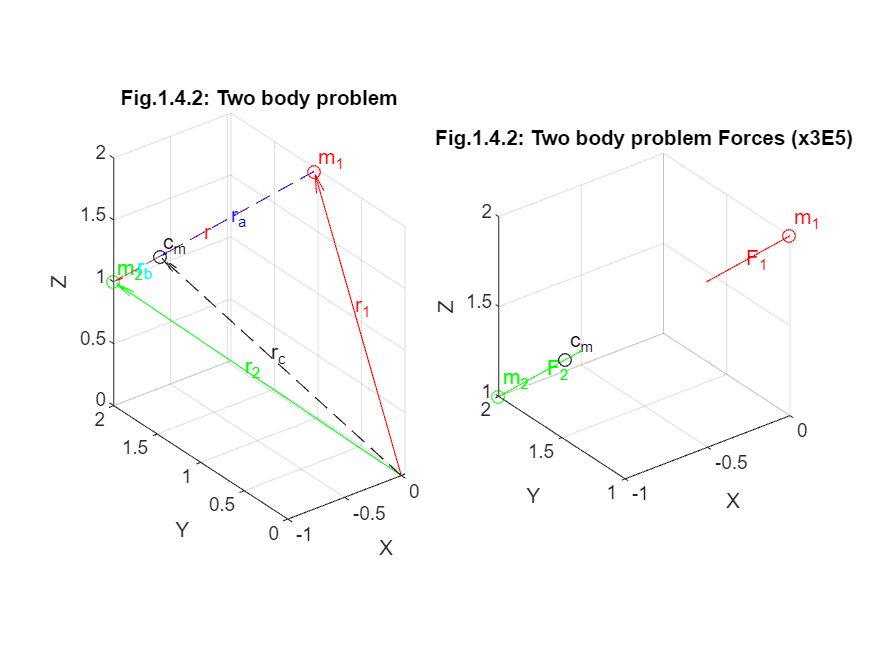

    %% Position and mass point properties
    r1 = [0,1,2]; m1 = 150;  %%Point 1
    r2 = [-1,2,1]; m2 = 500; %%Point 2 
    G =  6.668E-11;          %%m^3 / kg - s^2;
    
    %% Calculate center of mass
    cm = (r1*m1 + r2*m2)/(m1+m2);
    rc = cm;
    
    %% Calculate position relative to the center of mass
    r = r2-r1;
    ra = rc - r1;
    rb = r2 - rc;
    
    %% Calculate Forces
    F1 = G*m1*m2*(r2-r1)/(norm(r2-r1)^3);
    F2 = G*m1*m2*(r1-r2)/(norm(r1-r2)^3);
    
    %%% Plot figure
    figure()
    subplot(1,2,1)
        plotPoint (r1, 'ro', 'm_1', 0.05); hold on;
        plotPoint (r2, 'go', 'm_2', 0.05); plotPoint (cm, 'ko', 'c_m', 0.05);
        plotVector(r1, r, 1, 'r--', 'r', 'm');    plotVector(r1, ra, 1, 'b--', 'r_a', 'm'); 
        plotVector(rc, rb, 1, 'c--', 'r_b', 'm'); plotVector(zeros(1,3), r1, 1, 'r-', 'r_1', 'm'); 
        plotVector(zeros(1,3), r2, 1, 'g-', 'r_2', 'm'); plotVector(zeros(1,3), rc, 1, 'k--', 'r_c', 'm'); 
        title('Fig.1.4.2: Two body problem');
        xlabel('X'); ylabel('Y'); zlabel('Z');
        grid on;
    
    subplot(1,2,2)
        plotPoint (r1, 'ro', 'm_1', 0.05); hold on;
        plotPoint (r2, 'go', 'm_2', 0.05);         plotPoint (cm, 'ko', 'c_m', 0.05);
        plotVector(r1, F1, 3E5, 'r-', 'F_1', 'm'); plotVector(r2, F2, 3E5, 'g-', 'F_2', 'm'); 
        title('Fig.1.4.2: Two body problem Forces (x3E5)');
        xlabel('X'); ylabel('Y'); zlabel('Z')
        grid on;

#### 1.4.3. Translational Dynamics for a spacecraft.

To determine the translational dynamics of the satellite it is necessary to consider the orbit mechanics with Equations (1.4.6) and (1.4.7.) which are derived from (1.4.1) and (1.4.3).

$\ddot{x} = \frac{F_g}{m} + a_{pert}$  (1.4.6)

$F_g = \frac{-GMm}{|x|^2}\frac{x}{|x|}$ (1.4.7)

In the above equation, $G$ is the gravity constant, $M$ is the earth mass, $m$ is the satellite mass, and $x$ is the position vector expressed in the inertial frame. In addition, other gravitational disturbances $a_{pert}$   can be applied to the models. Several orbit propagators like the one explained in [6] which considers perturbations caused by earth albedo, solar pressure, gravitational force from Jupiter and others. Also other methods based on TLE like SPG4 orbit propagator are used to obtain accurate satellite position.

The following code implement the translational dynamics obtained by (1.4.6) and (1.4.7).

#### 1.4.4. Translational Dynamics simulation

%%%%Satellite parameters
sat.Is = [0.103682,-0.001094,0.015519;...
         -0.001094,0.104158,-2.57e-6;...
          0.015519,2.57e-6,0.088588];
sat.mass = 32; %Kg

%%%%This will define all of our planet parameters
earth.Radius       = 6378E3;               %% Planet Radius (meters)
earth.Mass         = 5.972E24;             %% Planet Mass (kg)
earth.GravityConst = 6.674E-11;            %% Planet gravity constan (Nm^2/kg^2)
earth.mu           = earth.GravityConst*earth.Mass;        %% G*M product (Nm^2/kg)

%% Orbit Parameters
%%%Orbital parameters
orbit.altitude    = 500E3;                                      % Meters
orbit.inclination = deg2rad(97.4);                              % SSO inclination (rad)
orbit.semi_major  = orbit.altitude+earth.Radius;                % Semi_major calculated knowing e = cero
orbit.period      = 2*pi/sqrt(earth.mu)*orbit.semi_major^(3/2); % Orbital period
orbit.vcircular   = sqrt(earth.mu/orbit.semi_major);            % Circular velocity
        
%% Initial Conditions
%%% Initial position in the fixed inertial frame (x,y,z)
initial.X.x0 = earth.Radius + orbit.altitude;     % Initial position x
initial.X.y0 = 0;                                 % Initial position y
initial.X.z0 = 0;                                 % Initial position z
%%%Calculate initial displacement rates
initial.Xdot.xdot0 = 0;
initial.Xdot.ydot0 = orbit.vcircular*cos(orbit.inclination);
initial.Xdot.zdot0 = orbit.vcircular*sin(orbit.inclination);

%% Simulation Parameters
%%% Setting Time Window (just 5 orbit)
settings.number_of_orbits = 5;
settings.tfinal = orbit.period*settings.number_of_orbits;
%%% Satellite initial states
settings.X0 = [initial.X.x0;            initial.X.y0;        initial.X.z0; ...
    initial.Xdot.xdot0; initial.Xdot.ydot0; initial.Xdot.zdot0];

%% Solve by variable step Runge Kutta of 4 order
tic
opts = odeset('InitialStep',1e-4,'RelTol',1e-6);
[tout,x] = ode45(@(t,x) satelliteTrans(t,x,earth,sat),...
    [0 settings.tfinal],settings.X0,opts);
elapsedTime = toc;

% Print the elapsed time in seconds
fprintf('Elapsed time: %.3f miliseconds\n',elapsedTime*1000);

Elapsed time: 68.247 miliseconds


%% Rename index
xyzout =   x(:,1:3);                            %%Satellite position(m)

Plot the orbit in 3D plot

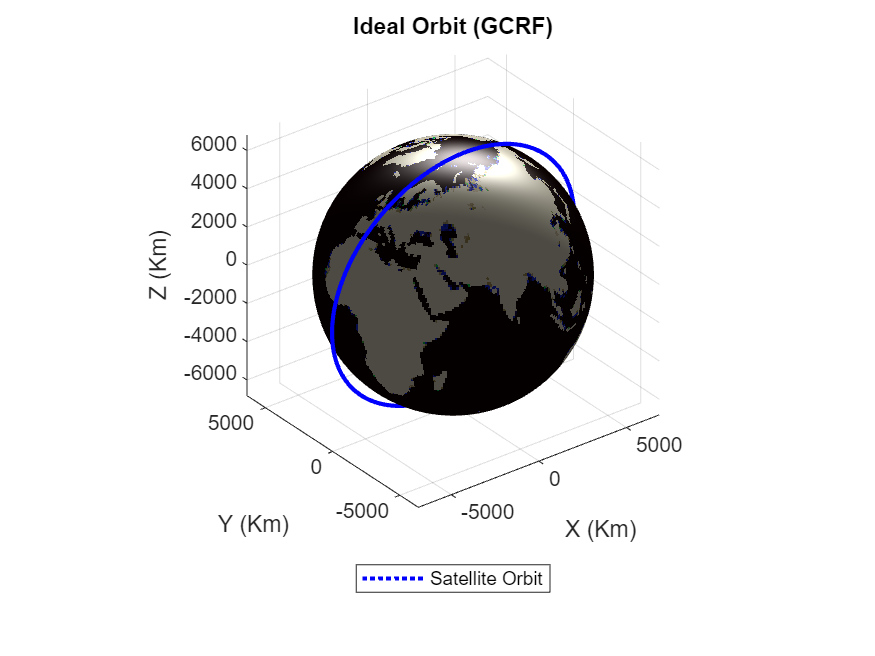

figure()
%% Plot 3D position
%%% Build Earth
% Load earth elevation data
load('topo.mat', 'topo', 'topomap1');
%% Obtain elevation data size
[rows, cols] = size(topo);

%% Create 3D earth sphere
[X, Y, Z] = sphere(rows-1, cols-1);
X = X*earth.Radius/1000;
Y = Y*earth.Radius/1000;
Z = Z*earth.Radius/1000;

% Draw earth in Km and satellite orbit
fig1 = figure();
set(fig1,'color','white')
h0 = plot3(xyzout(:,1)/1000,xyzout(:,2)/1000,xyzout(:,3)/1000,'b:','LineWidth',2);
xlabel('X (Km)')
ylabel('Y (Km)')
zlabel('Z (Km)')
grid on
hold on
surf(X, Y, Z,topo,'EdgeColor', 'none', 'FaceColor', 'texturemap', 'CDataMapping', 'direct');
legend(h0,'Satellite Orbit ','Location','southoutside');
colormap(topomap1);
axis equal
% Set view and ilumination
light('Position', [1 1 1]);
lighting gouraud;
view(3);
% Add title
title('Ideal Orbit (GCRF)')

#### **1.4.5. Satellite orbit Propagation**

To obtain more accurate simulations, a sateliite orbit propagation algorithm is neccessary. A satellite orbit propagation refers to the process of predicting and calculating the future positions and velocities of a satellite in a range of time. This prediction is based on mathematical models and equations of motion that take into account various forces and perturbations acting on the satellite, such as gravity, atmospheric drag, and solar radiation pressure. There are several orbital propagators but in this case we will focus on the  "Simplified Perturbations Gaussian" (SGP4) which bases its models in the two line elements (TLE) files. 

**a) Two Line elements (TLE):**

According to [5,7], the TLE is a data format encoding a list of orbital elements of an Earth-orbiting object for a given point in time generated by the North American Aerospace Defense Command (NORAD). Using a suitable prediction formula, with the TLE parameters the state (position and velocity) at any point in the past or future can be estimated to some accuracy. The TLE includes information about the satellite  and its orbit, such as satellite number, orbit inclination,  eccentricity, argument of perigee, derivatives of the  mean motion, mean anomaly, drag (BSTAR), ballistic  coefficient, ascending node, and revolution number [8].

The following tables developed by [5] are summarizes the information of the TLE columns.

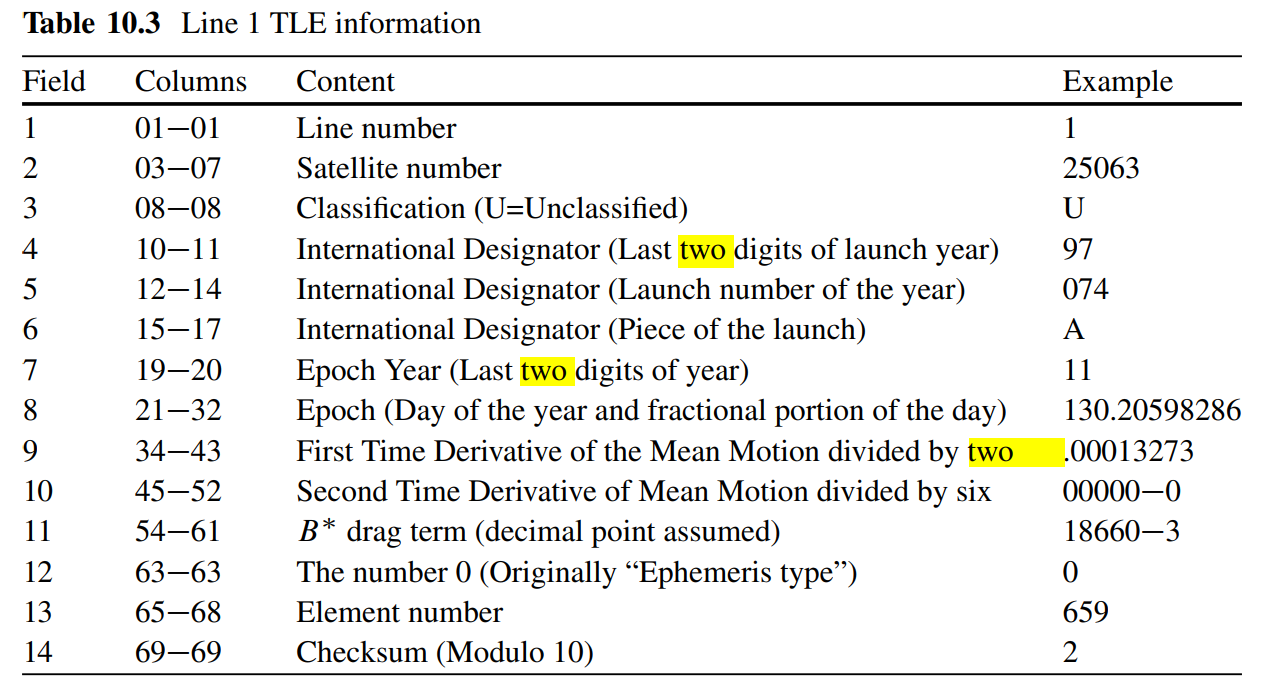 

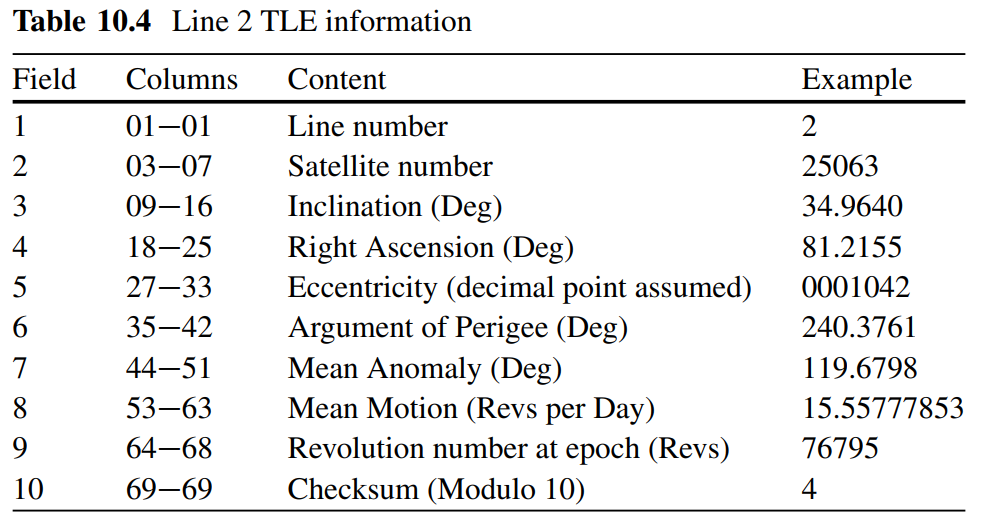

The following code shows a matlab Code that generates a TLE code.

% Orbital Parameters
tle.catNumber     = 20231;      % Catalog number of satellite (5 digits)
tle.clasification = 'U';        % Orbit clasiffication (U=unclassified)
tle.launchNumber  = 41;         % Launch number of the year
tle.pieceOfTheLaunch = 'A  ';   % Piece of the Launch (3 digits)
tle.epochYear = 2023;           % Epoch year of the TLE
tle.month = 08;                 % Month of the TLE
tle.day = 30;                   % Day of the TLE
tle.hour = 12;                  % Hour of the TLE
tle.minute =35;                 % Minute of the TLE
tle.seconds = 38;               % Seconds of the TLE
tle.dateTLE = datetime(tle.epochYear, tle.month,...
       tle.day,tle.hour, tle.minute, tle.seconds); 
tle.epochDay = day(tle.dateTLE, 'dayofyear') +...
    (tle.dateTLE.Hour + tle.dateTLE.Minute/60 + ...
    tle.dateTLE.Second/3600) / 24;     % Day of the year with fraction (12)
tle.dotMeanMotion2 = .00013273;
tle.dotdotMeanMotion6 = '00000-0 ';
tle.BdragTerm = '18660-3 ';
tle.ephemeridesType = '0';
tle.elementNumber = '001 ';


tle.inclination = 51.6;         % Inclinación orbital en grados
tle.raan = 120.5;               % Ascensión recta del nodo ascendente en grados
tle.eccentricity = 0.001;       % Excentricidad orbital
tle.argPerigee = 75.0;          % Argumento del perigeo en grados
tle.meanAnomaly = 0.0;          % Anomalía media en grados
tle.revolutionsPerDay = 15.0;   % Revoluciones por día

% Generate TLE lines
tleLine1    = repmat(' ', 1, 69);
tleLine1(1) = '1';
tleLine1(3:7) = num2str(tle.catNumber,'%05d');
tleLine1(8) = tle.clasification;
year =  num2str(tle.epochYear);
tleLine1(10:11) = year(end-1:end);
tleLine1(12:14) = num2str(tle.launchNumber,'%03d'); 
tleLine1(15:17) = tle.pieceOfTheLaunch;
tleLine1(19:20) = year(end-1:end);
tleLine1(21:32) = num2str(tle.epochDay,'%3.8f');
MeanMotion_dot_half = num2str(tle.dotMeanMotion2,'%1.9f');
tleLine1(34:43) = MeanMotion_dot_half(2:end); 
tleLine1(45:52) = tle.dotdotMeanMotion6;
tleLine1(54:61) = tle.BdragTerm;
tleLine1(63)    = tle.ephemeridesType;
tleLine1(65:68) = tle.elementNumber;
tleLine1(69)    = '0';

%% En este codigo falta añadir el check sum y el TLE para el Line 2
tleLine2 = sprintf('%05d  %8.4f %8.4f %07d %8.4f %8.4f %11.10f%d', ...
    tle.catNumber, tle.inclination, tle.raan, tle.eccentricity * 1e7, ...
                 tle.argPerigee, tle.meanAnomaly, tle.revolutionsPerDay, 999);

% Mostrar las líneas del TLE generadas
disp('Two-Line Elements:');

Two-Line Elements:


disp(tleLine1);

1 20231U 23041A   23242.52474537 .000132730 00000-0  18660-3  0 001 0


disp(tleLine2);

20231   51.6000 120.5000 0010000  75.0000   0.0000 15.0000000000999


**b) Orbit propagator (SPG4)**

The **SGP4** model is an orbit propagator developed in 1970, originally based on Brouwer’s theory of satellite motion perturbed by the Earth's zonal harmonics [8]. **SGP4** is capable of predicting a satellite's position in space when used in conjunction with the **TLE** elements developed by **NORAD** for each satellite. The **SGP4** model can predict perturbations caused by various factors, including the Earth's shape, atmospheric drag, radiation, and gravitational effects from other celestial bodies such as the sun and moon [8]. However, the **SGP4** propagator may experience a distance error of 1-3 km for each day in the future thats why the **TLE** must be updated each 12 hours to keep a rasonable error [8]. In [7] the **SGP4 **propagator is denoted as follows:  


$$\bar{y}(t) = f(\bar{x}_0,t)$$


Where $\bar{y}(t)$ is the state vector (position and velocity) at time $t$ and $f$ is the SPG4 model, and $\bar{x}_0$ is the mean orbital elements in the TLE ant epoch $t_0$. The SPG4 specific mean orbital elements $\bar{x}_0$ in TLE are.


$$\bar{x}_0 = (\bar{e}_0, \bar{i}_0, \bar{\Omega}_0, \bar{\omega}_0, \bar{M}_0, \bar{n}_0)$$


Where $\bar{e}_0$ is eccentricity, $\bar{i}_0$ is inclination, $\bar{\Omega}_0$ is right ascension of ascending node, $\bar{\omega}_0$ is argument of perigee, $\bar{M}_0$ is mean anomaly, and $\bar{n}_0$ is anomalistic mean motion. More detail about this algorithm can be seen in [SPACETRACK REPORT NO. 3 (celestrak.org)](https://celestrak.org/NORAD/documentation/spacetrk.pdf) and in [9].

In this project we wil use the **SPG4** matlab orbit propagator by using the `satelliteScenario` function. In the following code we will set the start time to 30-Ago-2023 12:35:38 PM UTC, the stop time to 01-Sep-2023 12:35:38 PM UTC, by using the `datetime` function, and the sample time to 60 seconds.

startTime = datetime(2023,08,30,12,35,38);
stopTime = startTime + days(1);
sampleTime = 120;
sc = satelliteScenario(startTime,stopTime,sampleTime);

And we set satellite orbital parameters as follows:

orbit.semiMajorAxis = 500E3+6378E3;
orbit.eccentricity = 0;
orbit.inclination = 97.34; 
orbit.rightAscensionOfAscendingNode = 313.131; 
orbit.argumentOfPeriapsis = 0; 
orbit.trueAnomaly = 0; 

Then we will create a satellite 

satSGP4 = satellite(sc, orbit.semiMajorAxis, orbit.eccentricity, orbit.inclination, ...
        orbit.rightAscensionOfAscendingNode, orbit.argumentOfPeriapsis, orbit.trueAnomaly);

Visualize Satellite scenario.

% v = satelliteScenarioViewer(sc);
% satSGP4.MarkerColor = [0 1 0];
% satSGP4.Orbit.LineColor = [0 1 0];
% satSGP4.LabelFontColor = [0 1 0];
% satSDP4.MarkerColor = [1 0 1];
% satSDP4.Orbit.LineColor = [1 0 1];
% satSDP4.LabelFontColor = [1 0 1];

 From the satellite object we can obtain its translational Dyamics in Geocentric Celestial Reference Frame (GCRF).

[positionSGP4,velocitySGP4, timeSGP4] = states(satSGP4);
ecefSPG4 = states(satSGP4,"CoordinateFrame", "ecef");
llaSPG4 = states(satSGP4,"CoordinateFrame", "geographic");


Finally, we will plot the obtained position.

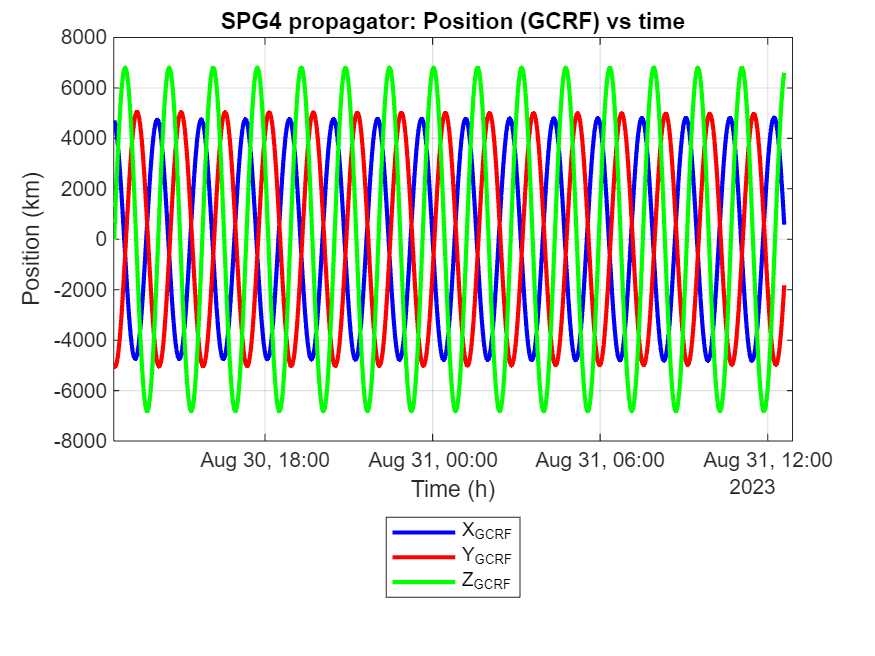

%% Plot 2D positionS
%%%Plot satellite GCRF position as a function of time
figure();
h1 = plot(timeSGP4,positionSGP4(1,:)/1E3,'b-','LineWidth',2);
hold on
grid on
h2 = plot(timeSGP4,positionSGP4(2,:)/1E3,'r-','LineWidth',2);
h3 = plot(timeSGP4,positionSGP4(3,:)/1E3,'g-','LineWidth',2);
xlabel('Time (h)');
ylabel('Position (km)');
legend([h1,h2,h3],'X_{GCRF}','Y_{GCRF}','Z_{GCRF}','Location','southoutside');
title('SPG4 propagator: Position (GCRF) vs time');
xlim([datetime(2023,8,30,12,34,48,'TimeZone','UTC')...
      datetime(2023,8,31,12,53,22,'TimeZone','UTC')])

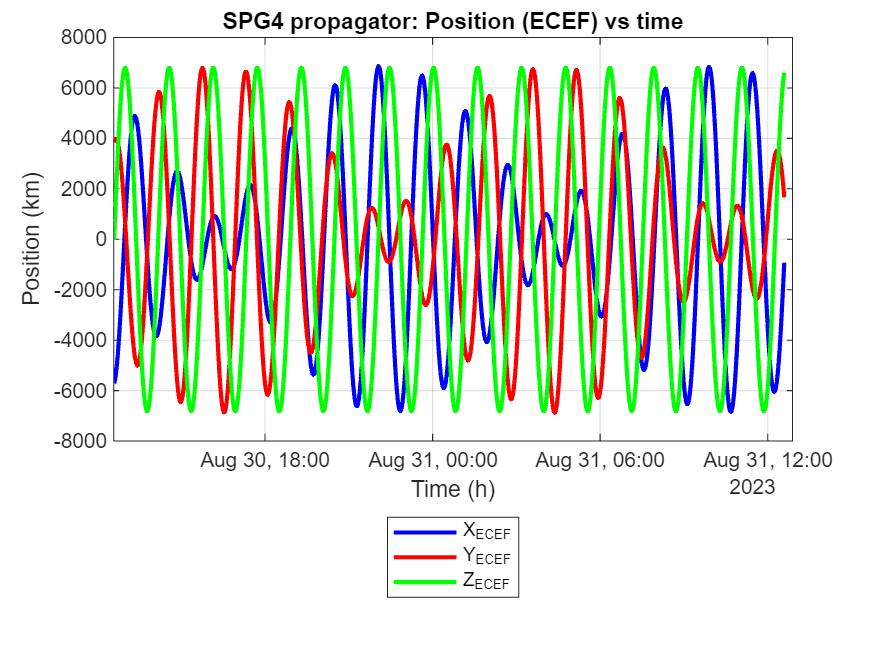

%%%Plot satellite GCRF position as a function of time
figure();
h1 = plot(timeSGP4,ecefSPG4(1,:)/1E3,'b-','LineWidth',2);
hold on
grid on
h2 = plot(timeSGP4,ecefSPG4(2,:)/1E3,'r-','LineWidth',2);
h3 = plot(timeSGP4,ecefSPG4(3,:)/1E3,'g-','LineWidth',2);
xlabel('Time (h)');
ylabel('Position (km)');
legend([h1,h2,h3],'X_{ECEF}','Y_{ECEF}','Z_{ECEF}','Location','southoutside');
title('SPG4 propagator: Position (ECEF) vs time');
xlim([datetime(2023,8,30,12,34,48,'TimeZone','UTC')...
      datetime(2023,8,31,12,53,22,'TimeZone','UTC')])

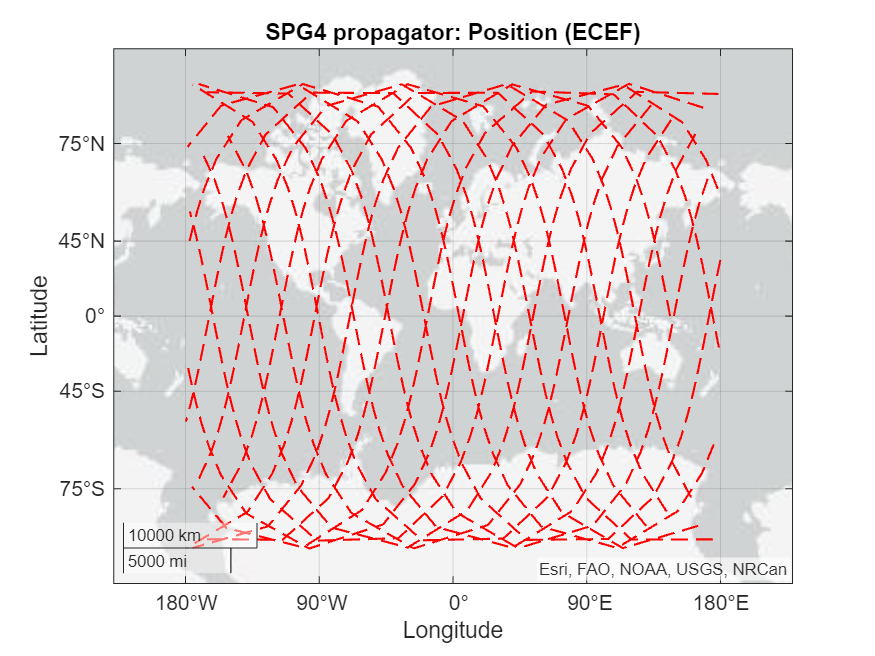

figure()
i_ant = 1;
for i = 2:length(llaSPG4)
    if (llaSPG4(2,i-1)<llaSPG4(2,i))
        geoplot(llaSPG4(1,i_ant:i-1),llaSPG4(2,i_ant:i-1),'r--','LineWidth',1);
        i_ant = i;
        hold on;
    end 
end
title('SPG4 propagator: Position (ECEF)');

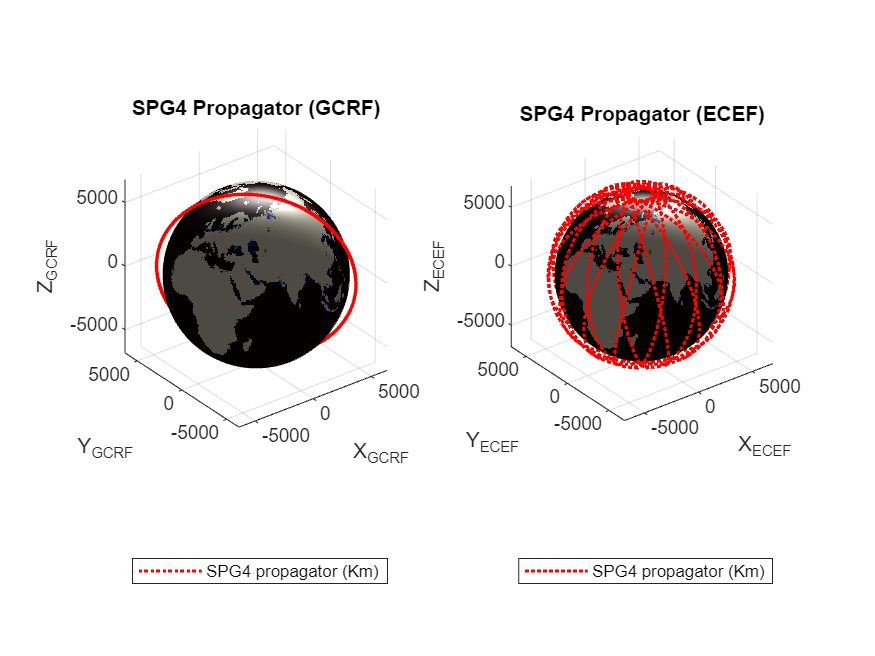

%% Plot 3D position
figure();
subplot(1,2,1);
%%% Build Earth
% Load earth elevation data
load('topo.mat', 'topo', 'topomap1');
%% Obtain elevation data size
[rows, cols] = size(topo);
%% Create 3D earth sphere
[X, Y, Z] = sphere(rows-1, cols-1);
X = X*earth.Radius/1000;
Y = Y*earth.Radius/1000;
Z = Z*earth.Radius/1000;
% Draw earth in Km and satellite orbit
h0 = plot3(positionSGP4(1,:)/1000,positionSGP4(2,:)/1000,positionSGP4(3,:)/1000,'r:','LineWidth',1.5);
xlabel('X_{GCRF}')
ylabel('Y_{GCRF}')
zlabel('Z_{GCRF}')
grid on
hold on
surf(X, Y, Z,topo,'EdgeColor', 'none', 'FaceColor', 'texturemap', 'CDataMapping', 'direct');
legend(h0,'SPG4 propagator (Km)','Location','southoutside');
colormap(topomap1);
axis equal
% Set view and ilumination
light('Position', [1 1 1]);
lighting gouraud;
view(3);
% Add title
title('SPG4 Propagator (GCRF)')
%% Plot 3D position

subplot(1,2,2)
% Draw earth in Km and satellite orbit
h0 = plot3(ecefSPG4(1,:)/1000,ecefSPG4(2,:)/1000,ecefSPG4(3,:)/1000,'r:','LineWidth',1.5);
xlabel('X_{ECEF}')
ylabel('Y_{ECEF}')
zlabel('Z_{ECEF}')
grid on
hold on
surf(X, Y, Z,topo,'EdgeColor', 'none', 'FaceColor', 'texturemap', 'CDataMapping', 'direct');
legend(h0,'SPG4 propagator (Km)','Location','southoutside');
colormap(topomap1);
axis equal
% Set view and ilumination
light('Position', [1 1 1]);
lighting gouraud;
view(3);
% Add title
title('SPG4 Propagator (ECEF)')

function [omega_dot] = mySatellite(t, omega, I , T_fun)
    %%%Global variables
    global varNames curValues varValues
    persistent availableVars
        
    %%% Inputs
    % I: Rigid body Inertia Tensor
    % omega: Angular Rate from B relative to I
    % T_fun: External Torques function
  
    %%%Movement equation (1.2.4)
    T=T_fun(t);  %%Get disturbances
    omega_dot = I\(T-cross(omega,I*omega));
    
    %%%---------Mechanism to store internal variables listed in varNames cell-------
    if t == 0
        % Find intersection between two cells considering time variable
        availableVars = intersect(who, varNames);
        
        % Check if there is an intersection
        if isempty(availableVars)
            disp('No variables are recording.');
        else
            disp('The following variables are recording.');
            disp(availableVars);
            varValues.time = [];
            for i = 1: length(availableVars)
                varValues.([availableVars{i, 1}]) = [];
            end
        end
    end
    
    if ~isempty(availableVars)
        for i = 1: length(availableVars)
            curValues.([availableVars{i, 1}]) = eval(reshape(availableVars{i, 1}, [], 1));
        end
    end
end

function x_dot = satelliteQuat(t,x,I,T_fun)
    %%%Global variables
    global varNames curValues varValues
    persistent availableVars
    
    %%Read variables
    q      =  x(1:4);
    omega  =  x(5:7);
    %%Get disturbances
    T=T_fun(t);  
    %%%Rotational Dynamics
    %%Book: Fundamentals of Spacecraft Attitude Determination and Control
    %%Author: F. Landis Markley & John L. Crassidis
    %%Quaternions Kinematics..Ecuación (2.88)
    Xi=[-q(2),-q(3),-q(4);
         q(1),-q(4),q(3);
         q(4),q(1),-q(2);
        -q(3),q(2),q(1)];
    q_dot=1/2*Xi*omega;
    %%%Dynamic equation (1.2.4)
    omega_dot = I\(T-cross(omega,I*omega));
    x_dot=[q_dot;omega_dot];
    
    %%%---------Mechanism to store internal variables listed in varNames cell-------
    if t == 0
        % Find intersection between two cells considering time variable
        availableVars = intersect(who, varNames);
        
        % Check if there is an intersection
        if isempty(availableVars)
            disp('No variables are recording.');
        else
            disp('The following variables are recording.');
            disp(availableVars);
            varValues.time = [];
            for i = 1: length(availableVars)
                varValues.([availableVars{i, 1}]) = [];
            end
        end
    end
    
    if ~isempty(availableVars)
        for i = 1: length(availableVars)
            curValues.([availableVars{i, 1}]) = eval(reshape(availableVars{i, 1}, [], 1));
        end
    end
end

function x_dot = satelliteTrans(t,x,earth,sat) %#ok
    %%% Read state input
    r   =  x(1:3);
    vel =  x(4:6);
    %% Read Satellite physical parameters
    m  = sat.mass;
    
    %%%Translational Dynamics
    %%%Earth gravity Model
    rho = norm(r);
    rhat = r/rho;
    Fgrav = -(earth.GravityConst*earth.Mass*m/rho^2)*rhat;
    F = Fgrav;
    accel = F/m;

   x_dot=[vel;accel];
end


function [h1,h2] = plotVector(v0,v,scale,style,label,labelLocation)
if labelLocation=='m'
    scale = scale*1.1;
    h1 = quiver3(v0(1), v0(2), v0(3), v(1)*scale, v(2)*scale, v(3)*scale, style);
    h2 = text(v0(1)+v(1)*scale/2,v0(2)+v(2)*scale/2, v0(3)+v(3)*scale/2, label,'Color',style(1));
else
    h1 = quiver3(v0(1)*scale, v0(2)*scale, v0(3)*scale, v(1)*scale, v(2)*scale, v(3)*scale, style);
    h2 = text((v0(1)+v(1))*scale, (v0(2)+v(2))*scale, (v0(3)+v(3))*scale, label,'Color',style(1));
end

% Set equal axis scales and display grid
axis equal
grid on
end

function [h1,h2] = plotPoint(P,style,label,pos)
h1 = plot3(P(1),P(2),P(3),style);
h2 = text(P(1)+pos,P(2)+pos,P(3)+pos,label,'Color',style(1));
end

function R = calculateRotationMatrix(u, theta)
    R = [cos(theta) + u(1)^2 * (1 - cos(theta)), u(1) * u(2) * (1 - cos(theta)) - u(3) * sin(theta), u(1) * u(3) * (1 - cos(theta)) + u(2) * sin(theta);
         u(2) * u(1) * (1 - cos(theta)) + u(3) * sin(theta), cos(theta) + u(2)^2 * (1 - cos(theta)), u(2) * u(3) * (1 - cos(theta)) - u(1) * sin(theta);
         u(3) * u(1) * (1 - cos(theta)) - u(2) * sin(theta), u(3) * u(2) * (1 - cos(theta)) + u(1) * sin(theta), cos(theta) + u(3)^2 * (1 - cos(theta))];
end

function T = stepper(t, Tin,iniTime, finTime)
    if t < iniTime
        T = zeros(3,1);
    elseif t > iniTime && t < finTime 
        T = Tin;
    else
        T = zeros(3,1);
    end
end

function rotX = quatRotation(q,x)
    qx = [0,x(1),x(2),x(3)]';
    qrotX = quatmultiply(quatmultiply(q', qx'), quatconj(q'));
    %qrotX = QuaternionsMultiplication(QuaternionsMultiplication(q,qx),QuaternionsConjugate(q));
    rotX = qrotX(2:4);
end

function [value, isterminal, direction] = store_var(t,x) %#ok
    
    global curValues varValues
    
     %%%Store Global variables
    fieldName = fields(curValues);
     
    varValues.time = horzcat(varValues.time, t);
     
    for i = 1:numel(fieldName)
       varValues.([fieldName{i,1}]) = horzcat(varValues.([fieldName{i,1}]), curValues.([fieldName{i, 1}]));
    end

    value = 1; % Evento siempre ocurre
    isterminal = 0; % No detener la simulación
    direction = 0; % Ambas direcciones
end

## **Bibliograpy**

[1] Yoon, H., Seo, H. H., & Choi, H. T. (2014). Optimal uses of reaction wheels in the pyramid configuration using a new minimum infinity-norm solution. *Aerospace Science and Technology*, *39*, 109-119.

[2] Sidi, M. J. (1997). *Spacecraft dynamics and control: a practical engineering approach* (Vol. 7). Cambridge university press.

[3] [5.2b. Elipsoide de inercia. - YouTube](https://www.youtube.com/watch?v=OrGo33sSGw0&ab_channel=V%C3%ADdeosdocentesdeIsraelCa%C3%B1am%C3%B3nValera)

[4] [Transport Theorem Worked Examples | Vector Derivatives When Frames are Rotating and Translating - YouTube](https://www.youtube.com/watch?v=RpavqEtXoXk&ab_channel=Dr.ShaneRoss)

[5] Markley, F. Landis, and John L. Crassidis. *Fundamentals of spacecraft attitude determination and control*. Vol. 1286. New York, NY: Springer New York, 2014.

[6]Flores, R., Burhani, B. M., & Fantino, E. (2021). A method for accurate and efficient propagation of satellite orbits: A case study for a Molniya orbit. *Alexandria Engineering Journal*, *60*(2), 2661-2676.

[7]Lee, Byoung-Sun, and Jae-Woo Park. "Estimation of the sgp4 drag term from two osculating orbit states." *Journal of Astronomy and Space Sciences* 20 (2003): 11-20.

[8]Liu, Zac Yung-Chun, et al. "Improved Orbital Propagator Integrated with SGP4 and Machine Learning." (2021).

[9]Hoots, Felix R., Paul W. Schumacher Jr, and Robert A. Glover. "History of analytical orbit modeling in the US space surveillance system." *Journal of Guidance, Control, and Dynamics* 27.2 (2004): 174-185.